syms theta r R d;
assumeAlso(theta>0);
assumeAlso(theta<pi/2);
assumeAlso(r>0);
assumeAlso(R>0);
assumeAlso(d>0);


eq = sqrt(d^2+r^2) - sqrt((d - R*sin(theta))^2 + (r - (R - R*cos(theta)))^2);
zeta = R/2 * sin(theta);
disp("Limit as d -> Inf");

Limit as d -> Inf


upper_limit = limit(eq, d, Inf)

$$upper\_limit = R\,\sin\left(\theta \right)$$

isAlways(upper_limit >= zeta)

ans = logical
   1


disp("Limit as d -> sqrt(3)*r");

Limit as d -> sqrt(3)*r


lower_limit = limit(eq, d, sqrt(3)*r)

$$lower\_limit = 2\,r-\sqrt{{\left(r-R+R\,\cos\left(\theta \right)\right)}^{2}+{\left(\sqrt{3}\,r-R\,\sin\left(\theta \right)\right)}^{2}}$$

isAlways(lower_limit >= zeta)

ans = logical
   0


l = 0.14;
V = 0.2;
actual_r = 0.085;
actual_theta = 2*V/(3*l);
min_d = sqrt(3)*actual_r

min_d = 0.1472

vertical_d = l * sin(actual_r)

vertical_d = 0.0119

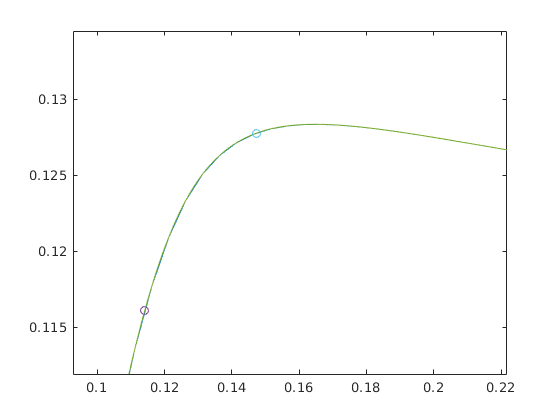

delta = subs(eq, [theta, r, R], [actual_theta, actual_r, l]);
ds = linspace(0, 0.5, 1000);
hold on;
ys = vpa(subs(delta, d, ds));
plot(ds, ys);
scatter(min_d, vpa(subs(delta, d, min_d)));
scatter(vertical_d, vpa(subs(delta, d, vertical_d)));

[max_val, argmax_index] = max(ys);
max_d = ds(argmax_index)

max_d = 0.1647

max_val

$$max\_val = 0.12835108208876577222065476907698$$